% CIV102 Bridge Design Project

clear; close all;

% Step 0: Initialize Parameters
L = 1200;   % Length of the bridge
n = 1200;   % Discretize into 1 mm segments
P = 400;    % Total weight of the train [N]
x = linspace(0, L, n+1);    % x-axis

% Step 1: SFD, BMD Under Train Loading
x_train = [52, 228, 392, 568, 732, 908]; % train load locations
P_train = [1 1 1 1 1 1] * (P/6);

n_train = 345;    % number of train start locations
SFDi = zeros(n_train, n+1);     % 1 SFD for each train start location
BMDi = zeros(n_train, n+1);     % 1 BMD for each train start location

for i = 1:n_train
    x_start_loc = i-52;  % start location of the train, acts like an adjustment factor
    x_train_adj = x_train + x_start_loc;  % adjusted train load locations

    % sum of moments at A equation, rearranged for R_y
    R_y = (sum(P_train .* x_train_adj)) / L;

    % sum of F_y equation, rearranged for L_y
    L_y = sum(P_train) - R_y;

    v = L_y; % initial shear force at left support
    SFDi(i, 1:x_train_adj(1)) = v; % filling in a shear force value for a given range of x-values
    v = v - P_train(1); % updating the shear force
    SFDi(i, x_train_adj(1):x_train_adj(2)) = v; % filling in the updated value for a given range of x-values
    v = v - P_train(2);
    SFDi(i, x_train_adj(2):x_train_adj(3)) = v;
    v = v - P_train(3);
    SFDi(i, x_train_adj(3):x_train_adj(4)) = v;
    v = v - P_train(4);
    SFDi(i, x_train_adj(4):x_train_adj(5)) = v;
    v = v - P_train(5);
    SFDi(i, x_train_adj(5):x_train_adj(6)) = v;
    v = v - P_train(6);
    SFDi(i, x_train_adj(6):n) = v;
    v = v + R_y;    % final shear force update at the right support
    SFDi(i, n+1) = v;
    
    BMDi(i,:) = cumtrapz(SFDi(i,:));   % integrating SFDi to get BMD
end

SFD = max(abs(SFDi));   % the absolute maximum values of shear force at all locations
BMD = max(BMDi);        % the maximum value of all bending moments at all locations
disp(BMDi(n+1))

  606.0000



disp (BMD)

   1.0e+04 *

         0    0.0256    0.0512    0.0767    0.1021    0.1275    0.1528    0.1780    0.2032    0.2283    0.2533    0.2783    0.3032    0.3280    0.3528    0.3775    0.4021    0.4267    0.4512    0.4756    0.5000    0.5243    0.5485    0.5727    0.5968    0.6208    0.6448    0.6687    0.6925    0.7163    0.7400    0.7636    0.7872    0.8107    0.8341    0.8575    0.8808    0.9040    0.9272    0.9503    0.9733    0.9963    1.0192    1.0420    1.0648    1.0875    1.1101    1.1327    1.1552    1.1776    1.2000    1.2223    1.2445    1.2667    1.2888    1.3108    1.3328    1.3547    1.3765    1.3983    1.4200    1.4416    1.4632    1.4847    1.5061    1.5275    1.5488    1.5700    1.5912    1.6123    1.6333    1.6543    1.6752    1.6960    1.7168    1.7375    1.7581    1.7787    1.7992    1.8196    1.8400    1.8603    1.8805    1.9007    1.9208    1.9408    1.9608    1.9807    2.0005    2.0203    2.0400    2.0596    2.0792    2.0987    2.1181    2.1375    2.1568    2.1760    2.

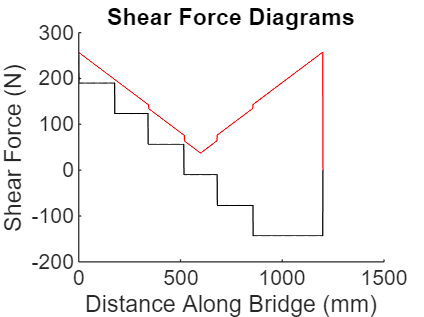

% Plotting the SFD and BMD
figure(1)
hold on
plot(x, SFDi(2,:), "k")
% plot(x, SFDi, 'k')  % SFD for individual location tests
plot(x, SFD, "r")   % SFD for maximum shear force
title("Shear Force Diagrams")
xlabel('Distance Along Bridge (mm)')
ylabel('Shear Force (N)')
hold off

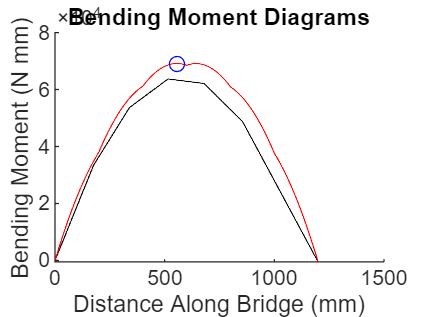


figure(2)
hold on
plot(x, BMDi(1,:), "k")
% plot(x, BMDi, "k")  % BMD for individual location tests
plot(x, BMD, "r")   % BMD for maximum bending moment
title("Bending Moment Diagrams")
xlabel('Distance Along Bridge (mm)')
ylabel('Bending Moment (N mm)')
[~, max_moment_idx] = max(BMD);  % find index of max moment
plot(max_moment_idx, BMD(max_moment_idx), "bo") % plot max moment
hold off


% <COMPLETE> 3. Calculate Sectional Properties
% WORKS Calculate the centroidal axis of i rectangles
base = [120, 1.27, 1.27, 10, 10, 0];
height = [3.81, 90, 90, 1.27, 1.27, 0];
area = base.*height;
y_i = [101.905, 50, 50, 99.365, 99.365, 0];
y_i_area_sum = sum(area.*y_i);
y_bar = y_i_area_sum / sum(area) % location of centroidal axis from the bottom

y_bar = 85.1305

disp(y_bar)

   85.1305



height_total = 103.81; % INPUT
y_bot = y_bar

y_bot = 85.1305

y_top = height_total - y_bar % INPUT

y_top = 18.6795


% WORKS Calculate the second moment of area, I
I_own = sum((base.*(height.^3))/12);
d = abs(y_bar - y_i);
I_par = sum(area.*(d.^2));
I = I_own + I_par

I = 5.7078e+05


% WORKS Q at centroidal axes
d_i = [(41.95955)]; % INPUT distance from centroidal axis to centroid of each area ABOVE OR BELOW (whichever easier) centroidal axis as ARRAY
A_i = [(1.27*83.9191)]; % INPUT area of rectangles ABOVE OR BELOW centroidal axis (whichever is easier)
Q_cent = sum(A_i.*d_i)

Q_cent = 4.4719e+03


% WORKS Q at glue location
d_glue = 15.2859; % distance from centroid of area of interest to centroid of entire cross-section
area_glue = 457.2; % area(s) that will slip and fall if the glue fails, can be one or many
Q_glue = area_glue*d_glue

Q_glue = 6.9887e+03


% <COMPLETE>   4. Calculate Applied Stress
V = SFD;
b_glue = 22.54; % INPUT area over which glue is spread, may be 2t
b_cent = 2*1.27; % INPUT aka t, thickness at axis of interest

fuck = max(BMD)

fuck = 6.9160e+04

fuckernum2 = max(SFD)

fuckernum2 = 257.3333

sigma_top = (fuck*y_top)/I

sigma_top = 2.2633

sigma_bot = (fuck*y_bot)/I

sigma_bot = 10.3150

tau_cent = (fuckernum2.*Q_cent)./(I*b_cent)

tau_cent = 0.7938

tau_glue = (fuckernum2.*Q_glue)./(I*b_glue)

tau_glue = 0.1398


% <COMPLETE> 5. Material and Thin Plate Buckling Capacities
% To calculate sigma_crit or=tau_crit for thin plate buckling.
% Choose one of four complete equations.
% WORKS Case #1 - 2 restrained, constant stress
k = 4;
E = 4000;
t = 3.81;
b = 103.81; % Change to height of the area of interest
poissons = 0.2;
sigma_buck1= ((k*pi^2*E)/12*(1-(poissons^2)))*((t/b)^2)

sigma_buck1 = 17.0169


% WORKS Case #2 - 1 restrained, constant stress
k = 0.425;
E = 4000;
t = 1.27;
b = 20; % Change to height of the area of interest
poissons = 0.2;
num_2 = (k*pi^2*E);
den_2 = 12*(1 - (poissons^2));
sigma_buck2 = (num_2 / den_2)*(t/b)^2

sigma_buck2 = 5.8728


% WORKS Case #3 - 2 restrained, variable stress
k = 6;
E = 4000;
t = 1.27;
b = 16.0809; % Change to height of the area of interest
poissons = 0.2;
num_3 = (k*pi^2*E);
den_3 = 12*(1 - (poissons^2));
sigma_buck3 = (num_3 / den_3)*(t/b)^2

sigma_buck3 = 128.2464


% WORKS Case #4 - 4 restrained, shear stress
k = 5;
E = 4000;
t = 1.27;
poissons = 0.2;
h = 101.27;
a = 245;
num_4 = 5*pi^2*E;
den_4 = 12*(1 - (poissons^2));
const_4 = ((t/h)^2) + ((t/a)^2);
sigma_buck4 = (num_4/den_4)*const_4

sigma_buck4 = 3.1552


sigma_tens = ones(1201, 1).*30; % Material props from the handout
sigma_comp = ones(1201, 1).*6;
tau_max = ones(1201, 1).*4;
tau_gluemax = ones(1201, 1).*2; % "Up to 2 if properly cured", if less than 2 days, take value between 0 and 2 
 
%<COMPLETE> 6. FOS
FOS_tens = min(sigma_tens'./ sigma_bot)

FOS_tens = 2.9084

FOS_comp = min(sigma_comp'./ sigma_top)

FOS_comp = 2.6510

FOS_shear = min(tau_max'./tau_cent)

FOS_shear = 5.0393

FOS_glue = min(tau_gluemax'./tau_glue) % 4 is given tau glue, other one is calculated tau (line 137)

FOS_glue = 14.3075

FOS_buck1 = min(sigma_buck1'./ sigma_top)

FOS_buck1 = 7.5185

FOS_buck2 = min(sigma_buck2'./ sigma_top)

FOS_buck2 = 2.5948

FOS_buck3 = min(sigma_buck3'./ sigma_top)

FOS_buck3 = 56.6627

FOS_buckV = min(sigma_buck4'./ tau_cent)

FOS_buckV = 3.9750

FOS = [FOS_tens FOS_comp FOS_shear FOS_glue FOS_buck1 FOS_buck2 FOS_buck3 FOS_buckV]

FOS =     2.9084    2.6510    5.0393   14.3075    7.5185    2.5948   56.6627    3.9750



% <INCOMPLETE> 7. Min FOS and the failure load Pfail
minFOS = min(FOS) % Min of all FOS values

minFOS = 2.5948

P_f = minFOS * P

P_f = 1.0379e+03


% <COMPLETE> 8. Vfail and Mfail
Mf_tens = FOS_tens.*BMD

Mf_tens = 1.0e+05 *

         0    0.0075    0.0149    0.0223    0.0297    0.0371    0.0444    0.0518    0.0591    0.0664    0.0737    0.0809    0.0882    0.0954    0.1026    0.1098    0.1170    0.1241    0.1312    0.1383    0.1454    0.1525    0.1595    0.1666    0.1736    0.1806    0.1875    0.1945    0.2014    0.2083    0.2152    0.2221    0.2289    0.2358    0.2426    0.2494    0.2562    0.2629    0.2697    0.2764    0.2831    0.2898    0.2964    0.3031    0.3097    0.3163    0.3229    0.3294    0.3360    0.3425


Mf_comp = FOS_comp.*BMD

Mf_comp = 1.0e+05 *

         0    0.0068    0.0136    0.0203    0.0271    0.0338    0.0405    0.0472    0.0539    0.0605    0.0672    0.0738    0.0804    0.0870    0.0935    0.1001    0.1066    0.1131    0.1196    0.1261    0.1325    0.1390    0.1454    0.1518    0.1582    0.1646    0.1709    0.1773    0.1836    0.1899    0.1962    0.2024    0.2087    0.2149    0.2211    0.2273    0.2335    0.2397    0.2458    0.2519    0.2580    0.2641    0.2702    0.2762    0.2823    0.2883    0.2943    0.3003    0.3062    0.3122


Vf_shear = FOS_shear.*BMD

Vf_shear = 1.0e+05 *

         0    0.0129    0.0258    0.0387    0.0515    0.0643    0.0770    0.0897    0.1024    0.1150    0.1277    0.1402    0.1528    0.1653    0.1778    0.1902    0.2026    0.2150    0.2274    0.2397    0.2520    0.2642    0.2764    0.2886    0.3007    0.3129    0.3249    0.3370    0.3490    0.3610    0.3729    0.3848    0.3967    0.4085    0.4203    0.4321    0.4439    0.4556    0.4672    0.4789    0.4905    0.5021    0.5136    0.5251    0.5366    0.5480    0.5594    0.5708    0.5821    0.5934


Vf_glue = FOS_glue.*BMD

Vf_glue = 1.0e+05 *

         0    0.0367    0.0733    0.1097    0.1461    0.1824    0.2186    0.2547    0.2907    0.3266    0.3625    0.3982    0.4338    0.4693    0.5048    0.5401    0.5754    0.6105    0.6456    0.6805    0.7154    0.7501    0.7848    0.8194    0.8539    0.8883    0.9225    0.9567    0.9908    1.0248    1.0588    1.0926    1.1263    1.1599    1.1934    1.2269    1.2602    1.2934    1.3266    1.3596    1.3926    1.4255    1.4582    1.4909    1.5235    1.5559    1.5883    1.6206    1.6528    1.6849


Mf_buck1 = FOS_buck1.*BMD

Mf_buck1 = 1.0e+05 *

         0    0.0193    0.0385    0.0577    0.0768    0.0959    0.1149    0.1339    0.1528    0.1716    0.1905    0.2092    0.2280    0.2466    0.2653    0.2838    0.3023    0.3208    0.3392    0.3576    0.3759    0.3942    0.4124    0.4306    0.4487    0.4668    0.4848    0.5028    0.5207    0.5386    0.5564    0.5741    0.5919    0.6095    0.6271    0.6447    0.6622    0.6797    0.6971    0.7145    0.7318    0.7491    0.7663    0.7835    0.8006    0.8176    0.8347    0.8516    0.8685    0.8854


Mf_buck2 = FOS_buck2.*BMD

Mf_buck2 = 1.0e+05 *

         0    0.0067    0.0133    0.0199    0.0265    0.0331    0.0396    0.0462    0.0527    0.0592    0.0657    0.0722    0.0787    0.0851    0.0915    0.0980    0.1043    0.1107    0.1171    0.1234    0.1297    0.1360    0.1423    0.1486    0.1549    0.1611    0.1673    0.1735    0.1797    0.1859    0.1920    0.1981    0.2043    0.2104    0.2164    0.2225    0.2285    0.2346    0.2406    0.2466    0.2526    0.2585    0.2645    0.2704    0.2763    0.2822    0.2881    0.2939    0.2997    0.3056


Mf_buck3 = FOS_buck3.*BMD

Mf_buck3 = 1.0e+06 *

         0    0.0145    0.0290    0.0435    0.0579    0.0722    0.0866    0.1009    0.1151    0.1294    0.1435    0.1577    0.1718    0.1859    0.1999    0.2139    0.2279    0.2418    0.2557    0.2695    0.2833    0.2971    0.3108    0.3245    0.3382    0.3518    0.3654    0.3789    0.3924    0.4059    0.4193    0.4327    0.4460    0.4594    0.4726    0.4859    0.4991    0.5123    0.5254    0.5385    0.5515    0.5645    0.5775    0.5904    0.6033    0.6162    0.6290    0.6418    0.6546    0.6673


Vf_buckV = FOS_buckV.*BMD

Vf_buckV = 1.0e+05 *

         0    0.0102    0.0204    0.0305    0.0406    0.0507    0.0607    0.0708    0.0808    0.0907    0.1007    0.1106    0.1205    0.1304    0.1402    0.1501    0.1598    0.1696    0.1794    0.1891    0.1988    0.2084    0.2180    0.2277    0.2372    0.2468    0.2563    0.2658    0.2753    0.2847    0.2942    0.3035    0.3129    0.3223    0.3316    0.3409    0.3501    0.3594    0.3686    0.3777    0.3869    0.3960    0.4051    0.4142    0.4233    0.4323    0.4413    0.4503    0.4592    0.4681
